# Experiment 1_2

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

## Part 6: aliasing in time domein

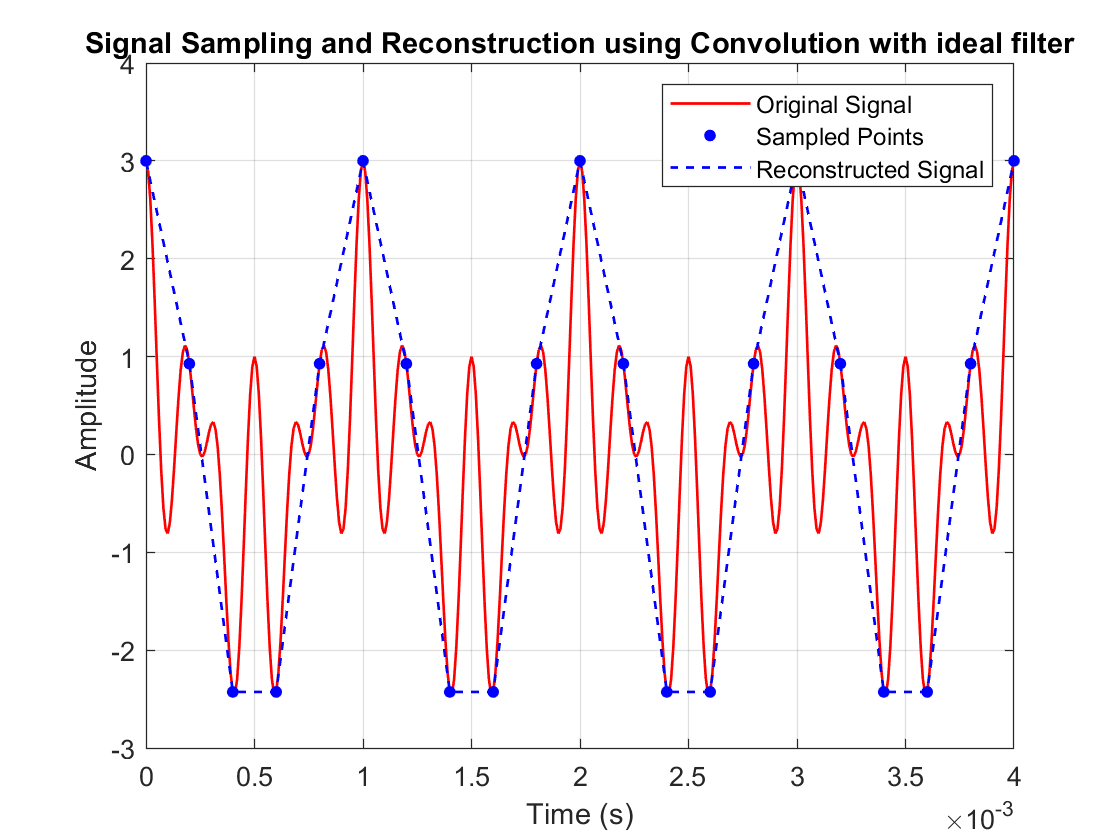

Ts = 0.00001;
t = 0:Ts:0.004;
x = cos(2*pi*1e3*t) + cos(8*pi*1e3*t) + cos(12*pi*1e3*t);
figure("Name", "original signal");
plot(t, x, LineWidth=1, Color='r');
title("original signal with samples");
hold on;
fs_low = 5e3;
t_sampled = 0:1/fs_low:0.004;
x_sampled = cos(2*pi*1e3*t_sampled) + cos(8*pi*1e3*t_sampled) + cos(12*pi*1e3*t_sampled);
plot(t_sampled, x_sampled, '.b', 'MarkerSize', 15);

% Reconstruction
L = 5; % reconstruction filter length
t_sinc = -L:1/fs_low:L;
sinc_filter = sinc(fs_low * t_sinc);

x_reconstructed_discrete = conv(x_sampled, sinc_filter, 'same'); 
t_reconstructed = linspace(0, 0.004, length(x_reconstructed_discrete));

plot(t_reconstructed, x_reconstructed_discrete, '--b', 'LineWidth', 1); 
legend('Original Signal', 'Sampled Points', 'Reconstructed Signal');
xlabel('Time (s)');
ylabel('Amplitude');
title('Signal Sampling and Reconstruction using Convolution with ideal filter');
grid on;

I expected that reconstructed signal would be the connection of dots with a straight line. Expectation was true as we can see in the figure above. It is because we didn't yake enough samples from our signal.

## Part 7: aliasing in frequency domein (part 1)

## Part 8: aliasing in frequency domein (part 2)

## Part 9: multi-rate filter banks

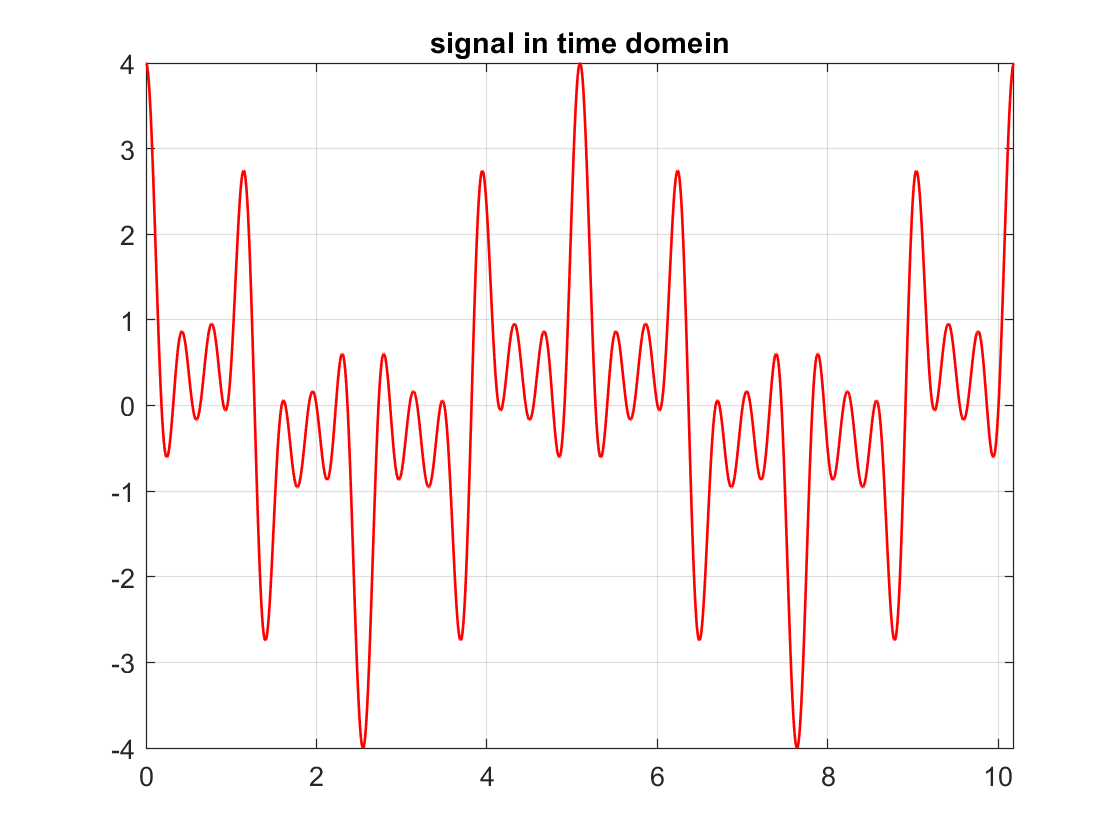

Ts = (16/pi)*0.0001;
t = 0:Ts:2*16/pi;
x = cos(2*pi*(pi/16)*t) + cos(2*pi*(5*pi/16)*t) + cos(2*pi*(9*pi/16)*t) + cos(2*pi*(13*pi/16)*t);
figure("Name", "signal in time domein");
plot(t, x, LineWidth=1, Color='r');
title("signal in time domein");
grid on;
xlim([0,2*16/pi]);

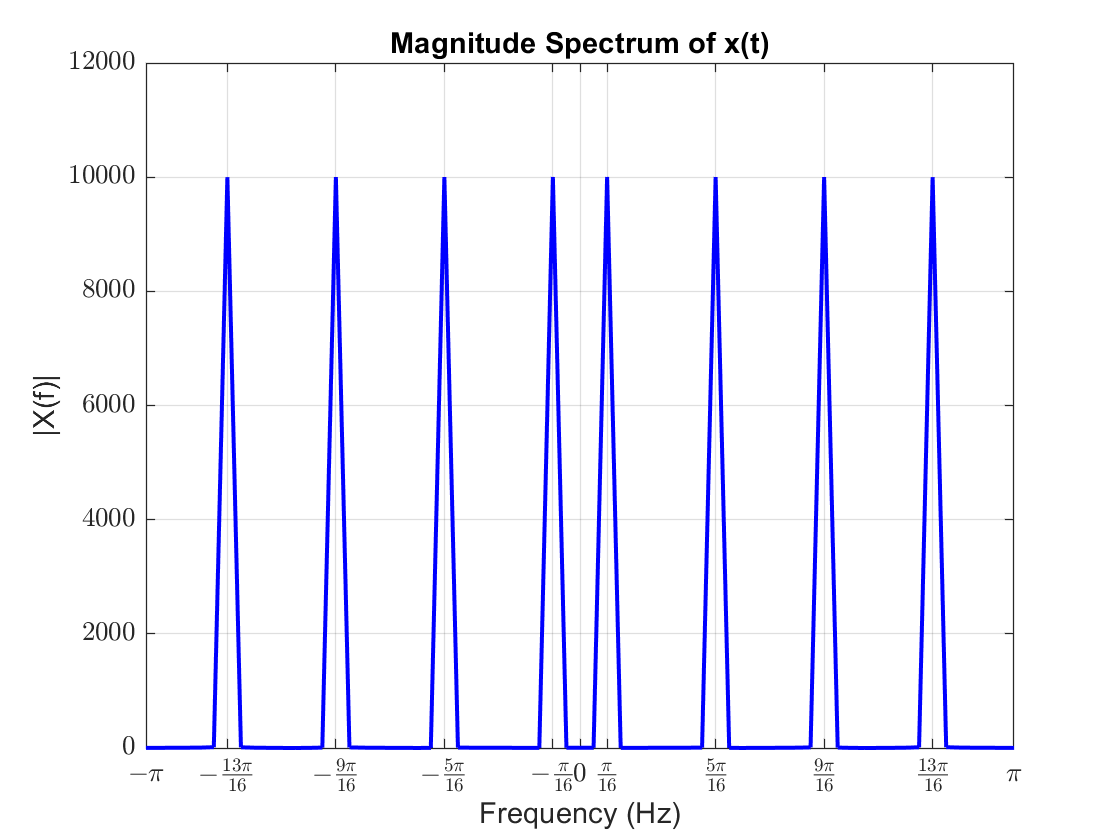

N = length(x); 
X_f = fft(x, N); 
X_f_shifted = fftshift(X_f); 

fs = 1/Ts; 
f = linspace(-fs/2, fs/2, N); 

figure("Name", "Frequency Domain");
plot(f, abs(X_f_shifted), 'LineWidth', 1.5, 'Color', 'b');
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Magnitude Spectrum of x(t)");
grid on;
xlim([-pi pi]);
xticks([-pi, -13*pi/16, -9*pi/16, -5*pi/16, -pi/16, 0, pi/16, 5*pi/16, 9*pi/16, 13*pi/16, pi]);
xticklabels({'$-\pi$', '$-\frac{13\pi}{16}$', '$-\frac{9\pi}{16}$', '$-\frac{5\pi}{16}$', ...
             '$-\frac{\pi}{16}$', '$0$', '$\frac{\pi}{16}$', '$\frac{5\pi}{16}$', ...
             '$\frac{9\pi}{16}$', '$\frac{13\pi}{16}$', '$\pi$'});
set(gca, 'TickLabelInterpreter', 'latex'); % Enable LaTeX formatting